# Composición de poses

1.- Implementar una función que calcule la composición de dos poses: 

    function p=tcomp(p1,p2)

 2.- Implementar un script de MATLAB que, partiendo de una pose inicial para el Robot de [-2.5,0,pi/2], calcule la composición de su pose con un comando de movimiento [Δ𝑥, Δ𝑦, Δ𝜃] = [0.2,0,−10°]

tcomp([-2.5 0 pi/2], [0.2 0 -10*pi/180])

ans =    -2.5000    0.2000    1.3963


3. Ejecutarlo durante 50 pasos visualizando la pose del robot. 

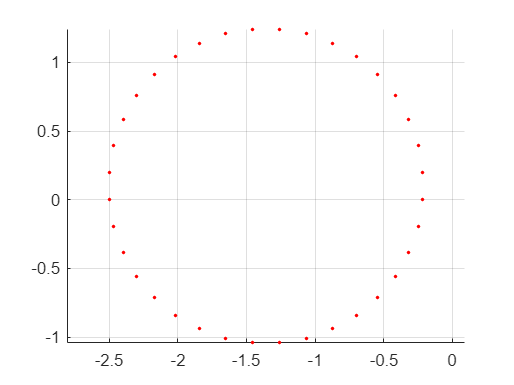

clear all;
close all;
figure(1); hold on; axis equal; grid on;

p = [-2.5 0 pi/2];
delta_p = [0.2 0 -10*pi/180];

for i = 1:50
    plot(p(1), p(2), 'r.');
    p = tcomp(p, delta_p);
end 

Modificarlo para que siga una trayectoria en espiral 

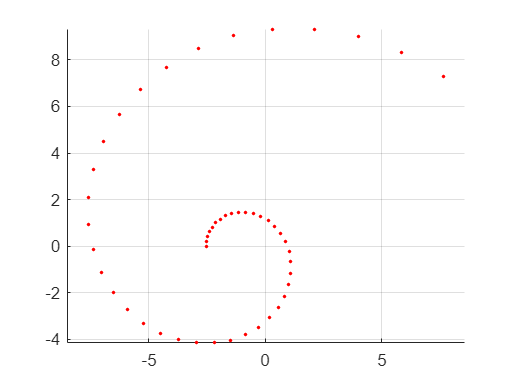

clear all;
close all;
figure(1); hold on; axis equal; grid on;

p = [-2.5 0 pi/2];
delta_p = [0.2 0 -10*pi/180];

for i = 1:50
    plot(p(1), p(2), 'r.');
    p = tcomp(p, delta_p);
    delta_p(1) = delta_p(1)*1.05;
end 

4. Implementar un script que permita al robot seguir un cuadrado 

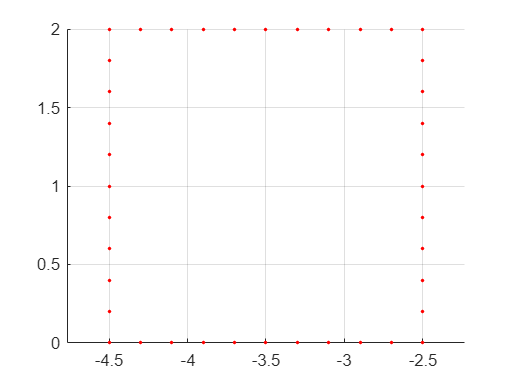

clear all;
close all;
figure(1); hold on; axis equal; grid on;

p = [-2.5 0 pi/2];
delta_recto = [0.2 0 0];
delta_giro  = [0.2 0 pi/2];

for i = 1:40
    plot(p(1), p(2), 'r.');
    if mod(i, 10) == 0 % llega a la esquina => girar
        delta = delta_giro;
    else
        delta = delta_recto;
    end
    p = tcomp(p, delta);
end 

5.- Dados s_r y s_l, el espacio recorrido por cada rueda calculado en base a la información de los encoders de un robot, calcular la trayectoria seguida por el mismo

## pendiente tutoría para preguntar